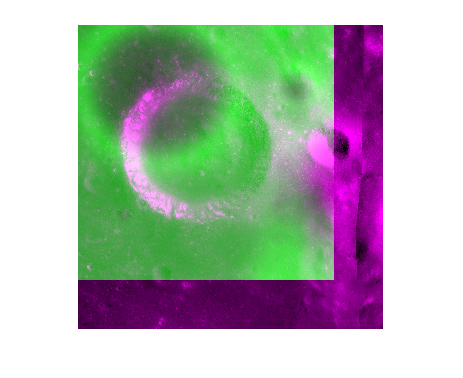

metric = registration.metric.MattesMutualInformation;
fixed  = imread("fixed.tiff");
moving = imread("moving.tiff");
figure
imshowpair(fixed, moving,'Scaling','joint');

optimizer = registration.optimizer.OnePlusOneEvolutionary;
metric = registration.metric.MattesMutualInformation

metric =   registration.metric.MattesMutualInformation

  プロパティ:
    NumberOfSpatialSamples: 500
     NumberOfHistogramBins: 50
              UseAllPixels: 1

optimizer.InitialRadius = 0.009;
optimizer.Epsilon = 1.5e-4;
optimizer.GrowthFactor = 1.01;
optimizer.MaximumIterations = 10000;
movingRegistered = imregister(moving,fixed,'affine',optimizer,metric);

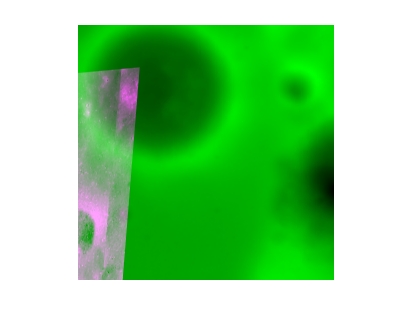

figure
imshowpair(fixed, movingRegistered,'Scaling','joint');

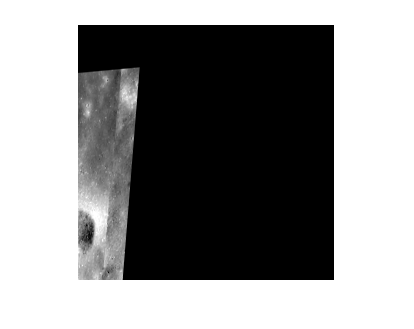

imshow(movingRegistered);